clear all;clc;

## Load or specify category labels

addpath(genpath('../helperFunctions/'))
allTasks = {'Camel_v2_test_nn','Camel_novel_v2_test_nn','Camel_Rhino_test_nn','Camel_background_matrix'};

d = natsortfiles(dir('./behaviorData/shrewData.mat'));
load([d(end).folder,'/',d(end).name])

exp_colors = flipud([179,128,206;...
    211,107,172;...
    254,153,132;...
    248,214,86]/256);

trial_colors = [62,159,44;...
    14,144,201;...
    30,57,155]/256;

shrewmarker = {'pentagram','^','s'};

train_perf = {};
test_perf = {};
all_perf = {};
for taskIdx = 1:3
    taskType = allTasks{taskIdx};
    camel0 = 1;

    allData.Camel_v2_test_nn.TestTarg(allData.Camel_v2_test_nn.TestTarg==398) = 198;

    all_targets = unique(allData.(taskType).T_Expt_ID);
    all_distractors = unique(allData.(taskType).D_Expt_ID);

    test_targets = [unique(allData.(taskType).TestTarg(~isnan(allData.(taskType).TestTarg))); unique(allData.(taskType).NovelTarg(~isnan(allData.(taskType).NovelTarg)))];
    % test_targets = unique(allData.(taskType).T_Expt_ID(isnan(allData.(taskType).ctch)));

    uShrew = unique(allData.(taskType).ShrewID);
    nShrew = length(uShrew);
    
    for ts = 1:nShrew
        % Extract behavioral performance
        avg_perf = nan(max(all_distractors)+1,max(all_targets)+1);
        for dd = 1:size(avg_perf,1)
            for tt = 1:size(avg_perf,2)
                avg_perf(dd,tt) = mean(allData.(taskType).correct(allData.(taskType).T_Expt_ID==tt-camel0 & allData.(taskType).D_Expt_ID==dd-camel0 & allData.(taskType).ShrewID==uShrew(ts)),'omitnan');
            end
        end

        test_targets = [unique(allData.(taskType).TestTarg(~isnan(allData.(taskType).TestTarg))); unique(allData.(taskType).NovelTarg(~isnan(allData.(taskType).NovelTarg)))];
        %     test_targets = unique(allData.(taskType).T_Expt_ID(isnan(allData.(taskType).ctch)));
        train_targets = setdiff(all_targets,test_targets);
        test_distractors = [unique(allData.(taskType).TestDist(~isnan(allData.(taskType).TestDist))); unique(allData.(taskType).NovelDist(~isnan(allData.(taskType).NovelDist)))];
        %     test_distractors = unique(allData.(taskType).D_Expt_ID(isnan(allData.(taskType).ctch)));
        train_distractors = setdiff(all_distractors,test_distractors);
        % disp([length(train_targets) length(test_targets); length(train_distractors) length(test_distractors)])

        train_perf{taskIdx,ts} = avg_perf(train_distractors+camel0,train_targets+camel0);
        test_perf{taskIdx,ts} = avg_perf(test_distractors+camel0,test_targets+camel0);
        all_perf{taskIdx,ts} = avg_perf(sort([train_distractors+camel0;test_distractors+camel0]), sort([train_targets+camel0;test_targets+camel0]));
    end
end

displayNSess = false;

% Determine which shrews to use
shrewname={'Seymour','Dominic','Ryker'};
shrewID = 1:3;
nIt = 1000;

sessionNTrials = cell(length(allTasks),length(shrewname));
sessionNTarg = cell(length(allTasks),length(shrewname));
sessionAcc_Catch = cell(1,length(allTasks));
sessionAcc_nonCatch = cell(1,length(allTasks));
sessionAcc_test = cell(1,length(allTasks));
sessionAcc_NovUnrew = cell(1,length(allTasks));
sessionAcc_NovRew = cell(1,length(allTasks));
sessionPerf_NovUnrew = cell(1,length(allTasks));
sessionPerf_NovRew = cell(1,length(allTasks));
sessionAcc_NovTarg = cell(1,length(allTasks));
sessionAcc_NovDist = cell(1,length(allTasks));
sessionAcc_NovBoth = cell(1,length(allTasks));
sessionAcc_Familiar = cell(1,length(allTasks));
sessionAcc_binned = cell(length(allTasks),length(shrewname));
sessionAcc_unbinned = cell(length(allTasks),length(shrewname));
targPerf = cell(length(allTasks),length(shrewname));
targdistPerf = cell(length(allTasks),length(shrewname));
targPerf_train = cell(length(allTasks),length(shrewname));
targdistPerf_train = cell(length(allTasks),length(shrewname));
targPerf_trainID = cell(length(allTasks),length(shrewname));
targPerf_test = cell(length(allTasks),length(shrewname));
targdistPerf_test = cell(length(allTasks),length(shrewname));
targPerf_split1 = cell(length(allTasks),length(shrewname));
targPerf_split2 = cell(length(allTasks),length(shrewname));
targdistPerf_split1 = cell(length(allTasks),length(shrewname));
targdistPerf_split2 = cell(length(allTasks),length(shrewname));
targdistPerf_test_split1 = cell(length(allTasks),length(shrewname));
targdistPerf_test_split2 = cell(length(allTasks),length(shrewname));
targdistPerf_train_split1 = cell(length(allTasks),length(shrewname));
targdistPerf_train_split2 = cell(length(allTasks),length(shrewname));
targSessPerf = cell(length(allTasks),length(shrewname));
targSessPerf_NovTest = cell(length(allTasks),length(shrewname));
targSessPerf_Train = cell(length(allTasks),length(shrewname));
targdistSessPerf = cell(length(allTasks),length(shrewname));
targSessPerf_split1 = cell(length(allTasks),length(shrewname));
targSessPerf_split2 = cell(length(allTasks),length(shrewname));
targdistSessPerf_split1 = cell(length(allTasks),length(shrewname));
targdistSessPerf_split2 = cell(length(allTasks),length(shrewname));
targPerf_test_split1 = cell(length(allTasks),length(shrewname));
targPerf_test_split2 = cell(length(allTasks),length(shrewname));
targPerf_train_split1 = cell(length(allTasks),length(shrewname));
targPerf_train_split2 = cell(length(allTasks),length(shrewname));

for task = 1:length(allTasks)
    nTarg = length(unique(allData.(allTasks{task}).T_Expt_ID));
    nDist = length(unique(allData.(allTasks{task}).D_Expt_ID));
    
    targID = unique(allData.(allTasks{task}).T_Expt_ID);
    distID = unique(allData.(allTasks{task}).D_Expt_ID);
    for ts = 1:length(shrewname)
        sessionIdx = unique(allData.(allTasks{task}).SessionID(allData.(allTasks{task}).ShrewID==ts));
        sessionNTrials{task,ts} = nan(1,length(sessionIdx));
        sessionNTarg{task,ts} = nan(1,length(sessionIdx));
        sessionAcc_Catch{task}{ts} = nan(1,length(sessionIdx));
        sessionAcc_nonCatch{task}{ts} = nan(1,length(sessionIdx));
        sessionAcc_NovUnrew{task}{ts} = nan(1,length(sessionIdx));
        sessionAcc_NovRew{task}{ts} = nan(1,length(sessionIdx));
        sessionPerf_NovUnrew{task}{ts} = {};
        sessionPerf_NovRew{task}{ts} = {};
        sessionAcc_NovTarg{task}{ts} = nan(1,length(sessionIdx));
        sessionAcc_NovDist{task}{ts} = nan(1,length(sessionIdx));
        sessionAcc_NovBoth{task}{ts} = nan(1,length(sessionIdx));
        sessionAcc_test{task}{ts} = nan(1,length(sessionIdx));
        sessionAcc_Familiar{task}{ts} = nan(1,length(sessionIdx));
        targSessPerf{task,ts} = nan(nTarg,length(sessionIdx));
        targSessPerf_NovTest{task,ts} = nan(nTarg,length(sessionIdx));
        targSessPerf_Train{task,ts} = nan(nTarg,length(sessionIdx));
        targdistSessPerf{task,ts} = nan(nTarg,nDist,length(sessionIdx));
        targSessPerf_split1{task,ts} = nan(nTarg,length(sessionIdx),nIt);
        targSessPerf_split2{task,ts} = nan(nTarg,length(sessionIdx),nIt);
        targdistSessPerf_split1{task,ts} = nan(nTarg,nDist,length(sessionIdx),nIt);
        targdistSessPerf_split2{task,ts} = nan(nTarg,nDist,length(sessionIdx),nIt);
        sessionAcc_binned{task,ts} = {};
        sessionAcc_unbinned{task,ts} = {};
        
        catchTrials = allData.(allTasks{task}).ctch == 1;
        noncatchTrials = allData.(allTasks{task}).ctch ~= 1;
        novUnrewTrials = isnan(allData.(allTasks{task}).ctch);
        novTargTrials = (allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).NovelTarg)==0;
        novDistTrials = (allData.(allTasks{task}).D_Expt_ID - allData.(allTasks{task}).NovelDist)==0;
        novBothTrials = ((allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).NovelTarg)==0 & (allData.(allTasks{task}).D_Expt_ID - allData.(allTasks{task}).NovelDist)==0) |...
            ((allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).TestTarg)==0 & (allData.(allTasks{task}).D_Expt_ID - allData.(allTasks{task}).TestDist)==0);
        anyNovTrials = (allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).NovelTarg)==0 | (allData.(allTasks{task}).D_Expt_ID - allData.(allTasks{task}).NovelDist)==0 |...
            (allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).TestTarg)==0 | (allData.(allTasks{task}).D_Expt_ID - allData.(allTasks{task}).TestDist)==0;
        NovTestTargs = (allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).NovelTarg)==0 | (allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).TestTarg)==0;
        novRewTrials = (allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).NovelTarg)==0 | (allData.(allTasks{task}).D_Expt_ID - allData.(allTasks{task}).NovelDist)==0;
        famTrials = ~anyNovTrials & ~catchTrials;
        
        if displayNSess
            disp([allTasks{task},', ',shrewname{ts},', NTarg = ',num2str(length(unique(allData.(allTasks{task}).T_Expt_ID(allData.(allTasks{task}).ShrewID==ts))))])
            disp([allTasks{task},', ',shrewname{ts},', NDist = ',num2str(length(unique(allData.(allTasks{task}).D_Expt_ID(allData.(allTasks{task}).ShrewID==ts))))])
        end
        
        for ss = 1:length(sessionIdx)
            sessionAcc_Catch{task}{ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & catchTrials),'omitnan');
            sessionAcc_nonCatch{task}{ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & noncatchTrials),'omitnan');
            sessionAcc_NovUnrew{task}{ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novUnrewTrials),'omitnan');
            sessionAcc_NovRew{task}{ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novRewTrials),'omitnan');
            sessionAcc_NovTarg{task}{ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novTargTrials),'omitnan');
            sessionAcc_NovDist{task}{ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novDistTrials),'omitnan');
            sessionAcc_NovBoth{task}{ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novBothTrials),'omitnan');
            sessionAcc_Familiar{task}{ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & famTrials),'omitnan');
            sessionNTrials{task,ts}(ss) = sum(allData.(allTasks{task}).SessionID==sessionIdx(ss));
            sessionNTarg{task,ts}(ss) = length(unique(allData.(allTasks{task}).T_Expt_ID(allData.(allTasks{task}).SessionID==sessionIdx(ss))));
            
            sessionPerf_NovUnrew{task}{ts}{ss} = allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novUnrewTrials);
            sessionPerf_NovRew{task}{ts}{ss} = allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novRewTrials);

            sessionAcc_unbinned{task,ts}{ss} = allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & allData.(allTasks{task}).ShrewID==shrewID(ts));

            binSize = 50;
            ntrials = sum(allData.(allTasks{task}).ShrewID==shrewID(ts) & allData.(allTasks{task}).SessionID==sessionIdx(ss));
            sessBin = 1:binSize:ntrials;
            sessionAcc_binned{task,ts}{ss} = nan(1,length(sessBin)-1);
            for bb = 1:length(sessBin)-1
                binIdx = allData.(allTasks{task}).Trial_in_sess>=sessBin(bb) & allData.(allTasks{task}).Trial_in_sess<sessBin(bb+1);
                sessionAcc_binned{task,ts}{ss}(bb) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & allData.(allTasks{task}).ShrewID==shrewID(ts) & binIdx),'omitnan');
            end

            for tt = 1:nTarg
                ntrials = sum(allData.(allTasks{task}).ShrewID==shrewID(ts) & allData.(allTasks{task}).T_Expt_ID==targID(tt) & allData.(allTasks{task}).SessionID==sessionIdx(ss));
                
                if ntrials >= 10
                    inclusion = allData.(allTasks{task}).ShrewID==shrewID(ts) & allData.(allTasks{task}).T_Expt_ID==targID(tt) & allData.(allTasks{task}).SessionID==sessionIdx(ss);
                    targSessPerf{task,ts}(tt,ss) = mean(allData.(allTasks{task}).correct(inclusion),'omitnan');
                    targSessPerf_NovTest{task,ts}(tt,ss) = mean(allData.(allTasks{task}).correct(inclusion & NovTestTargs),'omitnan');
                    targSessPerf_Train{task,ts}(tt,ss) = mean(allData.(allTasks{task}).correct(inclusion & famTrials),'omitnan');
                    for samp = 1:nIt
                        idx = find(inclusion);
                        nidx_split = round(length(idx)/2);
                        rp = randperm(length(idx));
                        split1 = idx(rp(1:nidx_split));
                        split2 = idx(rp(nidx_split+1:end));
                        targSessPerf_split1{task,ts}(tt,ss,samp) = mean(allData.(allTasks{task}).correct(split1),'omitnan');
                        targSessPerf_split2{task,ts}(tt,ss,samp) = mean(allData.(allTasks{task}).correct(split2),'omitnan');
                    end
                end
            end
        end
        
        for tt = 1:nTarg
            ntrials = sum(allData.(allTasks{task}).ShrewID==shrewID(ts) & allData.(allTasks{task}).T_Expt_ID==targID(tt));
            targPerf{task,ts}(tt) = nan;
            targdistPerf{task,ts}(tt,:) = nan(1,nDist);
            targPerf_train{task,ts}(tt) = nan;
            targdistPerf_train{task,ts}(tt,:) = nan(1,nDist);
            targPerf_trainID{task,ts}(tt) = nan;
            targPerf_test{task,ts}(tt) = nan;
            targdistPerf_test{task,ts}(tt,:) = nan(1,nDist);
            targPerf_split1{task,ts}(tt,:) = nan(1,nIt);
            targPerf_split2{task,ts}(tt,:) = nan(1,nIt);
            targdistPerf_split1{task,ts}(tt,:,:) = nan(nDist,nIt);
            targdistPerf_split2{task,ts}(tt,:,:) = nan(nDist,nIt);
            targdistPerf_test_split1{task,ts}(tt,:,:) = nan(nDist,nIt);
            targdistPerf_test_split2{task,ts}(tt,:,:) = nan(nDist,nIt);
            targdistPerf_train_split1{task,ts}(tt,:,:) = nan(nDist,nIt);
            targdistPerf_train_split2{task,ts}(tt,:,:) = nan(nDist,nIt);
            targPerf_test_split1{task,ts}(tt,:) = nan(1,nIt);
            targPerf_test_split2{task,ts}(tt,:) = nan(1,nIt);
            targPerf_train_split1{task,ts}(tt,:) = nan(1,nIt);
            targPerf_train_split2{task,ts}(tt,:) = nan(1,nIt);
            if ntrials >= 10
                inclusion = allData.(allTasks{task}).ShrewID==shrewID(ts) & allData.(allTasks{task}).T_Expt_ID==targID(tt);
                targPerf{task,ts}(tt) = mean(allData.(allTasks{task}).correct(inclusion),'omitnan');
                inclusion_test = allData.(allTasks{task}).ShrewID==shrewID(ts) & allData.(allTasks{task}).T_Expt_ID==targID(tt) & novBothTrials;
                targPerf_test{task,ts}(tt) = mean(allData.(allTasks{task}).correct(inclusion_test),'omitnan');
                inclusion_train = allData.(allTasks{task}).ShrewID==shrewID(ts) & allData.(allTasks{task}).T_Expt_ID==targID(tt) & famTrials;
                targPerf_train{task,ts}(tt) = mean(allData.(allTasks{task}).correct(inclusion_train),'omitnan');
                if ~isempty(unique(allData.(allTasks{task}).T_Expt_ID(inclusion_train)))
                    targPerf_trainID{task,ts}(tt) = unique(allData.(allTasks{task}).T_Expt_ID(inclusion_train));
                end

                for dd = 1:nDist
                    ntrials = sum(allData.(allTasks{task}).ShrewID==shrewID(ts) & allData.(allTasks{task}).T_Expt_ID==targID(tt) & allData.(allTasks{task}).D_Expt_ID==distID(dd));
                    if ntrials >= 10
                        inclusion = allData.(allTasks{task}).ShrewID==shrewID(ts) & allData.(allTasks{task}).T_Expt_ID==targID(tt) & allData.(allTasks{task}).D_Expt_ID==distID(dd);
                        targdistPerf{task,ts}(tt,dd) = mean(allData.(allTasks{task}).correct(inclusion),'omitnan');
                        targdistPerf_train{task,ts}(tt,dd) = mean(allData.(allTasks{task}).correct(inclusion & inclusion_train),'omitnan');
                        targdistPerf_test{task,ts}(tt,dd) = mean(allData.(allTasks{task}).correct(inclusion & inclusion_test),'omitnan');

                        for samp = 1:nIt
                            idx = find(inclusion);
                            nidx_split = round(length(idx)/2);
                            rp = randperm(length(idx));
                            split1 = idx(rp(1:nidx_split));
                            split2 = idx(rp(nidx_split+1:end));
                            targdistPerf_split1{task,ts}(tt,dd,samp) = mean(allData.(allTasks{task}).correct(split1),'omitnan');
                            targdistPerf_split2{task,ts}(tt,dd,samp) = mean(allData.(allTasks{task}).correct(split2),'omitnan');

                            idx = find(inclusion & inclusion_train);
                            nidx_split = round(length(idx)/2);
                            rp = randperm(length(idx));
                            split1 = idx(rp(1:nidx_split));
                            split2 = idx(rp(nidx_split+1:end));
                            targdistPerf_train_split1{task,ts}(tt,dd,samp) = mean(allData.(allTasks{task}).correct(split1),'omitnan');
                            targdistPerf_train_split2{task,ts}(tt,dd,samp) = mean(allData.(allTasks{task}).correct(split2),'omitnan');

                            idx = find(inclusion & inclusion_test);
                            nidx_split = round(length(idx)/2);
                            rp = randperm(length(idx));
                            split1 = idx(rp(1:nidx_split));
                            split2 = idx(rp(nidx_split+1:end));
                            targdistPerf_test_split1{task,ts}(tt,dd,samp) = mean(allData.(allTasks{task}).correct(split1),'omitnan');
                            targdistPerf_test_split2{task,ts}(tt,dd,samp) = mean(allData.(allTasks{task}).correct(split2),'omitnan');
                        end
                    end
                end

                for samp = 1:nIt
                    idx = find(inclusion);
                    nidx_split = round(length(idx)/2);
                    rp = randperm(length(idx));
                    split1 = idx(rp(1:nidx_split));
                    split2 = idx(rp(nidx_split+1:end));
                    targPerf_split1{task,ts}(tt,samp) = mean(allData.(allTasks{task}).correct(split1),'omitnan');
                    targPerf_split2{task,ts}(tt,samp) = mean(allData.(allTasks{task}).correct(split2),'omitnan');
                    idx = find(inclusion_test);
                    nidx_split = round(length(idx)/2);
                    rp = randperm(length(idx));
                    split1 = idx(rp(1:nidx_split));
                    split2 = idx(rp(nidx_split+1:end));
                    targPerf_test_split1{task,ts}(tt,samp) = mean(allData.(allTasks{task}).correct(split1),'omitnan');
                    targPerf_test_split2{task,ts}(tt,samp) = mean(allData.(allTasks{task}).correct(split2),'omitnan');
                    idx = find(inclusion_train);
                    nidx_split = round(length(idx)/2);
                    rp = randperm(length(idx));
                    split1 = idx(rp(1:nidx_split));
                    split2 = idx(rp(nidx_split+1:end));
                    targPerf_train_split1{task,ts}(tt,samp) = mean(allData.(allTasks{task}).correct(split1),'omitnan');
                    targPerf_train_split2{task,ts}(tt,samp) = mean(allData.(allTasks{task}).correct(split2),'omitnan');
                end
            end
        end
    end
end

## Plot between-shrew correlations of target/distractor performance

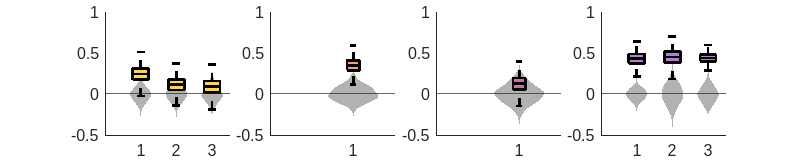

Se vs Do, r = 0.24707, p = 1
Se vs Ry, r = 0.12718, p = 0
Do vs Ry, r = 0.092139, p = 0
Se vs Do, r = 0.35374, p = 1
Do vs Ry, r = 0.12165, p = 0
Se vs Do, r = 0.43337, p = 1
Se vs Ry, r = 0.4551, p = 1
Do vs Ry, r = 0.44305, p = 1


figure('Renderer', 'painters', 'Position', [10 10 1500 300]);hold on;
perf_r = {};
perf_r_boot = {};
r_perm = {};
p_human975 = {};
for task = 1:length(allTasks)
    subplot(1,length(allTasks),task);hold on;
    nShrews = length(unique(allData.(allTasks{task}).ShrewID));
    uniqueShrew = unique(allData.(allTasks{task}).ShrewID);
    cmap = [255,113,183;218,85,2;255,176,0] / 255;
    idx_comb = [1,2;1,3;2,3];
    if nShrews < 3
        cmap = cmap(sum(idx_comb,2)==sum(uniqueShrew),:);
        idx_comb = uniqueShrew';
        nShrews = 1;
    end
    for i = 1:nShrews
        y1 = targdistPerf{task,idx_comb(i,1)};
        y2 = targdistPerf{task,idx_comb(i,2)};
        [perf1,perf2,xFit,yFit] = corr_fun(y1(:),y2(:));
        
        perf_r{task}(i) = corr(perf1,perf2,'rows','complete','Type','Spearman');
        perf_r_boot{task}(i,:) = bootstrp(1000,@(x,y) corr(x,y,'rows','complete','Type','Spearman'),perf1,perf2);

        for j = 1:nIt
            numtarg = length(perf1);
            idx1 = randperm(numtarg);
            idx2 = randperm(numtarg);
            r_perm{task}(i,j) = corr(perf1(idx1),perf2(idx2),'Rows','complete');
        end

        CI975_human = mean(r_perm{task}(i,:)) + 1.96*(std(r_perm{task}(i,:)));
        p_human975{task}(i) = mean(perf_r{task}(i))>CI975_human;

        disp([shrewname{shrewID(idx_comb(i,1))}(1:2),' vs ',shrewname{shrewID(idx_comb(i,2))}(1:2),', r = ',num2str(mean(perf_r{task}(i))),', p = ',num2str(p_human975{task}(i))])
    end

    h1 = boxplot(perf_r_boot{task}','colors',[0 0 0],'symbol','');
    set(h1,{'linew'},{2})

    h1 = findobj(gca,'Tag','Box');
    for j=1:size(perf_r_boot{task},1)
       temp = get(h1(j),'XData');
       violin(r_perm{task}(j,:)','x',(temp(1)+temp(3))/2,'edgecolor','none','facecolor',[0.4 0.4 0.4],'mc',[],'medc',[]);
    end

    h1 = findobj(gca,'Tag','Box');
    for j=1:size(perf_r_boot{task},1)
       patch(get(h1(j),'XData'),get(h1(j),'YData'),exp_colors(task,:),'FaceAlpha',1);
    end
    h1 = boxplot(perf_r_boot{task}','colors',[0 0 0],'symbol','');
    set(h1,{'linew'},{2})

    box off
    
    ylim([-0.5 1])
    yline(0)
end

## Within-shrew target/distractor correlations w null comparisons

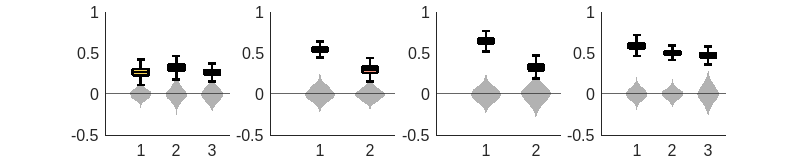

figure('Renderer', 'painters', 'Position', [10 10 1500 300]);hold on;
for task = 1:length(allTasks)
    subplot(1,length(allTasks),task);hold on;
    nShrews = length(unique(allData.(allTasks{task}).ShrewID));
    uniqueShrew = unique(allData.(allTasks{task}).ShrewID);
    r_perm{task} = nan(length(uniqueShrew),nIt);
    perf_r_boot{task} = nan(length(uniqueShrew),nIt);
    % cmap = [255,113,183;218,85,2;255,176,0] / 255;
    if nShrews < 3
        % cmap = cmap(sum(idx_comb,2)==sum(uniqueShrew),:);
        idx_comb = uniqueShrew';
        nShrews = 1;
    end
    if task ==3
        uniqueShrew = [1,2]';
    end
    for i = uniqueShrew'
        if task==3
            y1 = targdistPerf_split1{task,i+1};
            y2 = targdistPerf_split2{task,i+1};
        else
            y1 = targdistPerf_split1{task,i};
            y2 = targdistPerf_split2{task,i};
        end

        for j = 1:nIt
            [perf1,perf2,xFit,yFit] = corr_fun(y1(:,:,j),y2(:,:,j));

            numtarg = length(perf1);
            idx1 = randperm(numtarg);
            idx2 = randperm(numtarg);
            
            perf_r_boot{task}(i,j) = corr(perf1,perf2,'rows','complete','Type','Spearman');
            r_perm{task}(i,j) = corr(perf1(idx1),perf2(idx2),'Rows','complete');

        end
        
        perf_r{task}(i) = mean(perf_r_boot{task}(i,:));

        CI975_human = mean(r_perm{task}(i,:)) + 1.96*(std(r_perm{task}(i,:)));
        p_human975{task}(i) = mean(perf_r{task}(i))>CI975_human;
    end

    h1 = boxplot(perf_r_boot{task}','colors',[0 0 0],'symbol','');
    set(h1,{'linew'},{2})

    h1 = findobj(gca,'Tag','Box');
    for j=1:size(perf_r_boot{task},1)
       temp = get(h1(j),'XData');
       violin(r_perm{task}(j,:)','x',(temp(1)+temp(3))/2,'edgecolor','none','facecolor',[0.4 0.4 0.4],'mc',[],'medc',[]);
    end

    h1 = findobj(gca,'Tag','Box');
    for j=1:size(perf_r_boot{task},1)
       patch(get(h1(j),'XData'),get(h1(j),'YData'),exp_colors(task,:),'FaceAlpha',1);
    end
    h1 = boxplot(perf_r_boot{task}','colors',[0 0 0],'symbol','');
    set(h1,{'linew'},{2})

    box off
    ylim([-0.5 1])
    yline(0)
end